clear all
Name = 'P3O190_3rd';
Cali_Left = 60/760;
Cali_Right = 60/(1188-670);
LData = readtable(['Left_', Name, '.csv']);
RData = readtable(['Right_',Name, '.csv']);
L = min(length(LData.y), length(RData.y)); 
for i = 1:L
    LPoints{i} = [LData.x(i), LData.y(i)] * Cali_Left;
    RPoints{i} = [RData.x(i), RData.y(i)] * Cali_Right;
end

tracksL=simpletracker(LPoints,'Debug',true,'MaxLinkingDistance',50,'MaxGapClosing',5);

Frame to frame linking using Hungarian method.
181/181
Creating 181 links over a total of 182 points.
Done.
Gap-closing:
Done.
Building tracks:


ans = 0.0055

ans = 0.0110

ans = 0.0165

ans = 0.0220

ans = 0.0275

ans = 0.0330

ans = 0.0385

ans = 0.0440

ans = 0.0495

ans = 0.0549

ans = 0.0604

ans = 0.0659

ans = 0.0714

ans = 0.0769

ans = 0.0824

ans = 0.0879

ans = 0.0934

ans = 0.0989

ans = 0.1044

ans = 0.1099

ans = 0.1154

ans = 0.1209

ans = 0.1264

ans = 0.1319

ans = 0.1374

ans = 0.1429

ans = 0.1484

ans = 0.1538

ans = 0.1593

ans = 0.1648

ans = 0.1703

ans = 0.1758

ans = 0.1813

ans = 0.1868

ans = 0.1923

ans = 0.1978

ans = 0.2033

ans = 0.2088

ans = 0.2143

ans = 0.2198

ans = 0.2253

ans = 0.2308

ans = 0.2363

ans = 0.2418

ans = 0.2473

ans = 0.2527

ans = 0.2582

ans = 0.2637

ans = 0.2692

ans = 0.2747

ans = 0.2802

ans = 0.2857

ans = 0.2912

ans = 0.2967

ans = 0.3022

ans = 0.3077

ans = 0.3132

ans = 0.3187

ans = 0.3242

ans = 0.3297

ans = 0.3352

ans = 0.3407

ans = 0.3462

ans = 0.3516

ans = 0.3571

ans = 0.3626

ans = 0.3681

ans = 0.3736

ans = 0.3791

ans = 0.3846

ans = 0.3901

ans = 0.3956

ans = 0.4011

ans = 0.4066

ans = 0.4121

ans = 0.4176

ans = 0.4231

ans = 0.4286

ans = 0.4341

ans = 0.4396

ans = 0.4451

ans = 0.4505

ans = 0.4560

ans = 0.4615

ans = 0.4670

ans = 0.4725

ans = 0.4780

ans = 0.4835

ans = 0.4890

ans = 0.4945

ans = 0.5000

ans = 0.5055

ans = 0.5110

ans = 0.5165

ans = 0.5220

ans = 0.5275

ans = 0.5330

ans = 0.5385

ans = 0.5440

ans = 0.5495

ans = 0.5549

ans = 0.5604

ans = 0.5659

ans = 0.5714

ans = 0.5769

ans = 0.5824

ans = 0.5879

ans = 0.5934

ans = 0.5989

ans = 0.6044

ans = 0.6099

ans = 0.6154

ans = 0.6209

ans = 0.6264

ans = 0.6319

ans = 0.6374

ans = 0.6429

ans = 0.6484

ans = 0.6538

ans = 0.6593

ans = 0.6648

ans = 0.6703

ans = 0.6758

ans = 0.6813

ans = 0.6868

ans = 0.6923

ans = 0.6978

ans = 0.7033

ans = 0.7088

ans = 0.7143

ans = 0.7198

ans = 0.7253

ans = 0.7308

ans = 0.7363

ans = 0.7418

ans = 0.7473

ans = 0.7527

ans = 0.7582

ans = 0.7637

ans = 0.7692

ans = 0.7747

ans = 0.7802

ans = 0.7857

ans = 0.7912

ans = 0.7967

ans = 0.8022

ans = 0.8077

ans = 0.8132

ans = 0.8187

ans = 0.8242

ans = 0.8297

ans = 0.8352

ans = 0.8407

ans = 0.8462

ans = 0.8516

ans = 0.8571

ans = 0.8626

ans = 0.8681

ans = 0.8736

ans = 0.8791

ans = 0.8846

ans = 0.8901

ans = 0.8956

ans = 0.9011

ans = 0.9066

ans = 0.9121

ans = 0.9176

ans = 0.9231

ans = 0.9286

ans = 0.9341

ans = 0.9396

ans = 0.9451

ans = 0.9505

ans = 0.9560

ans = 0.9615

ans = 0.9670

ans = 0.9725

ans = 0.9780

ans = 0.9835

ans = 0.9890

ans = 0.9945

ans = 1

ans = 2

ans = 3

trajL=rt2traj(LPoints,tracksL,5);
trajL=trajp2traj(trajL,1/200);
tracksR=simpletracker(RPoints,'Debug',true,'MaxLinkingDistance',50,'MaxGapClosing',5);

Frame to frame linking using Hungarian method.
181/181
Creating 181 links over a total of 182 points.
Done.
Gap-closing:
Done.
Building tracks:


ans = 0.0055

ans = 0.0110

ans = 0.0165

ans = 0.0220

ans = 0.0275

ans = 0.0330

ans = 0.0385

ans = 0.0440

ans = 0.0495

ans = 0.0549

ans = 0.0604

ans = 0.0659

ans = 0.0714

ans = 0.0769

ans = 0.0824

ans = 0.0879

ans = 0.0934

ans = 0.0989

ans = 0.1044

ans = 0.1099

ans = 0.1154

ans = 0.1209

ans = 0.1264

ans = 0.1319

ans = 0.1374

ans = 0.1429

ans = 0.1484

ans = 0.1538

ans = 0.1593

ans = 0.1648

ans = 0.1703

ans = 0.1758

ans = 0.1813

ans = 0.1868

ans = 0.1923

ans = 0.1978

ans = 0.2033

ans = 0.2088

ans = 0.2143

ans = 0.2198

ans = 0.2253

ans = 0.2308

ans = 0.2363

ans = 0.2418

ans = 0.2473

ans = 0.2527

ans = 0.2582

ans = 0.2637

ans = 0.2692

ans = 0.2747

ans = 0.2802

ans = 0.2857

ans = 0.2912

ans = 0.2967

ans = 0.3022

ans = 0.3077

ans = 0.3132

ans = 0.3187

ans = 0.3242

ans = 0.3297

ans = 0.3352

ans = 0.3407

ans = 0.3462

ans = 0.3516

ans = 0.3571

ans = 0.3626

ans = 0.3681

ans = 0.3736

ans = 0.3791

ans = 0.3846

ans = 0.3901

ans = 0.3956

ans = 0.4011

ans = 0.4066

ans = 0.4121

ans = 0.4176

ans = 0.4231

ans = 0.4286

ans = 0.4341

ans = 0.4396

ans = 0.4451

ans = 0.4505

ans = 0.4560

ans = 0.4615

ans = 0.4670

ans = 0.4725

ans = 0.4780

ans = 0.4835

ans = 0.4890

ans = 0.4945

ans = 0.5000

ans = 0.5055

ans = 0.5110

ans = 0.5165

ans = 0.5220

ans = 0.5275

ans = 0.5330

ans = 0.5385

ans = 0.5440

ans = 0.5495

ans = 0.5549

ans = 0.5604

ans = 0.5659

ans = 0.5714

ans = 0.5769

ans = 0.5824

ans = 0.5879

ans = 0.5934

ans = 0.5989

ans = 0.6044

ans = 0.6099

ans = 0.6154

ans = 0.6209

ans = 0.6264

ans = 0.6319

ans = 0.6374

ans = 0.6429

ans = 0.6484

ans = 0.6538

ans = 0.6593

ans = 0.6648

ans = 0.6703

ans = 0.6758

ans = 0.6813

ans = 0.6868

ans = 0.6923

ans = 0.6978

ans = 0.7033

ans = 0.7088

ans = 0.7143

ans = 0.7198

ans = 0.7253

ans = 0.7308

ans = 0.7363

ans = 0.7418

ans = 0.7473

ans = 0.7527

ans = 0.7582

ans = 0.7637

ans = 0.7692

ans = 0.7747

ans = 0.7802

ans = 0.7857

ans = 0.7912

ans = 0.7967

ans = 0.8022

ans = 0.8077

ans = 0.8132

ans = 0.8187

ans = 0.8242

ans = 0.8297

ans = 0.8352

ans = 0.8407

ans = 0.8462

ans = 0.8516

ans = 0.8571

ans = 0.8626

ans = 0.8681

ans = 0.8736

ans = 0.8791

ans = 0.8846

ans = 0.8901

ans = 0.8956

ans = 0.9011

ans = 0.9066

ans = 0.9121

ans = 0.9176

ans = 0.9231

ans = 0.9286

ans = 0.9341

ans = 0.9396

ans = 0.9451

ans = 0.9505

ans = 0.9560

ans = 0.9615

ans = 0.9670

ans = 0.9725

ans = 0.9780

ans = 0.9835

ans = 0.9890

ans = 0.9945

ans = 1

ans = 2

ans = 3

trajR=rt2traj(RPoints,tracksR,5);
trajR=trajp2traj(trajR,1/200);


% x = trajL.x;
% y = trajL.y;
% figure(1)
% img = im2double(imread('P3O190\3rd\Left\Left0100.tif'));
% img = img/max(max(img));
% imshow(img);
% hold on;
% plot(x/Cali_Left,y/Cali_Left,'Color','r','LineWidth',2);
% hold off
% xL = (y - y(10));
% zL = x(1) - x;


w = trajL.u;
u = trajL.v;

% figure(3)
% scatter(x/Cali_Left,y/Cali_Left);

% x = trajR.x;
% y = trajR.y;
% figure(2)
% img = im2double(imread('P3O190\3rd\Right\Right0130.tif'));
% img = img/max(max(img));
% imshow(img);
% hold on;
% plot(x/Cali_Right,y/Cali_Right,'Color','r','LineWidth',2);
% hold off;
% yR = (y(1) - y);

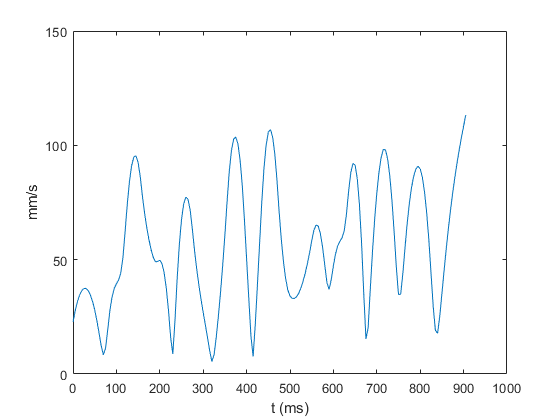

v = trajR.v;
figure
uprime = sqrt(v.^2 + u.^2);
xplot = (0:(length(u)-1))*1/200*1000;
plot(xplot, uprime)
ylim([0,150]);
xlabel('t (ms)')
ylabel('mm/s')
saveas(gca,[Name,'Uprime.jpg'])

V = zeros(10000,1);
V(1:length(u)) = v

V =    14.3966
   16.8157
   18.7922
   20.3261
   21.4175
   22.0663
   22.2726
   22.0363
   21.3575
   20.2361


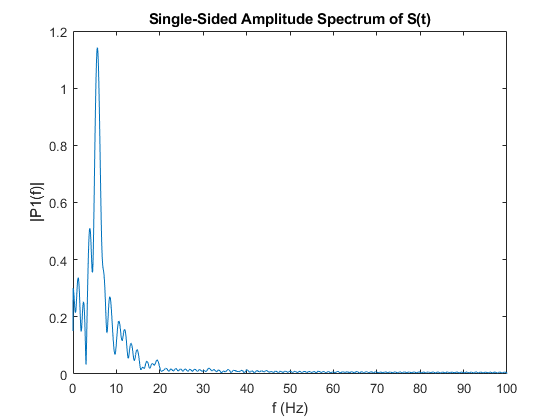

sp = fft(V);
L = length(V);
P2 = abs(sp/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = 200*(0:(L/2))/L;
figure
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')
saveas(gca,[Name,'VelocitySpectrum.jpg'])

% figure(4)
% scatter(x/Cali_Right,yR/Cali_Right)

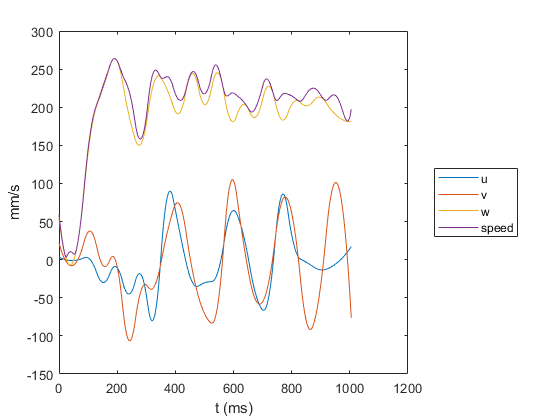

% traj3D = [xL,zL,yR];
%save([Name,'.mat'],'traj3D');
figure(5)
xplot = (0:(length(u)-1))*1/200 * 1000;
speed = sqrt(u.^2 + v.^2 + w.^2);
w = -w;
plot(xplot,u);
hold on;
plot(xplot,v);
hold on;
plot(xplot,w);
hold on;
plot(xplot,speed);
hold off;
legend('u','v','w','speed', 'Location', 'eastoutside');
xlabel('t (ms)');
ylabel('mm/s');
saveas(gca,[Name,'.jpg']);

V = zeros(10000,1);
V(1:L) = trajL.x

Unable to perform assignment because the left and right sides have a different number of elements.

sp = fft(V);
L = length(V);
P2 = abs(sp/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = 200*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

Plot the top view of trajectory

clear all;
Name = 'P3O190_3rd';
load([Name,'.mat']);
figure(1)
plot(traj3D(:,1),traj3D(:,3));
xlabel('X');
ylabel('Y');
axis equal
xlim([-15, 15])
ylim([-15, 15])
saveas(gca,[Name,'TopView.jpg']);
